Problem7

a = 1+mod(109,3)

a = 2

Fs = 44100

Fs = 44100

load ConvFile2.txt % as a = 2 
h = ConvFile2

h =     0.0000
   -0.0000
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0003


j = "Track00" + a + ".wav"

j = "Track002.wav"

[s,Fs] = audioread(j)

s =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

sound(s,Fs) %original track
x= conv2(s,h)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


audiowrite("sg3.wav",x,Fs)
sound(x,Fs) %convoluted track
% plot of fft of original
z = size(s) %size of original track

z =       811631           1


T = 1/Fs;             % Sampling period       
L = z(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P2 = abs(s/L);
P1 = P2(1:L/2+1);

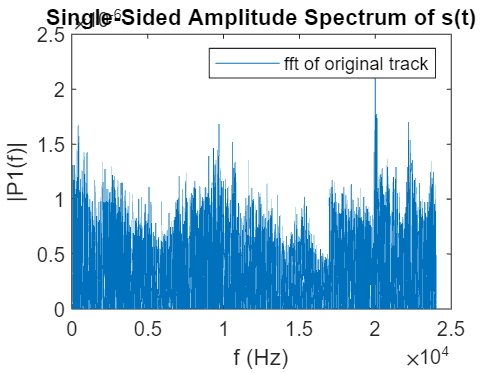

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title("Single-Sided Amplitude Spectrum of s(t)")
legend("fft of original track")
xlabel("f (Hz)")
ylabel("|P1(f)|")

% plot of fft of convoluted track
k = size(x) % size of convoluted track

k =       811831           1


T = 1/Fs;             % Sampling period       
L = k(1);             % Length of signal
t = (0:L-1)*T;    % Time vector
P4 = abs(x/L);
P3 = P4(1:L/2+1);

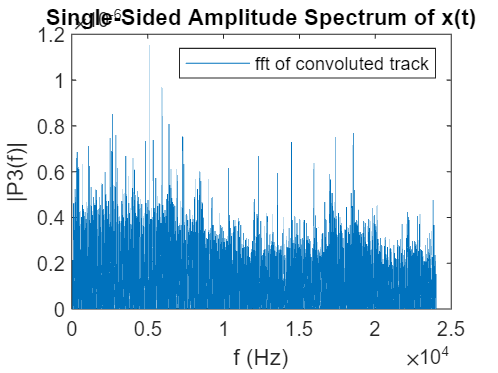

P3(2:end-1) = 2*P3(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P3) 
title("Single-Sided Amplitude Spectrum of x(t)")
legend("fft of convoluted track")
xlabel("f (Hz)")
ylabel("|P3(f)|")